Author: **Arjan Gupta**

Due: April 10, 2023

Class: RBE 501

Institution: Worcester Polytechnic Institute

clear; close all; clc;

## Preliminary Setup

### Build Denso's HSR robot with Robotics Toolkit

In the prompt of this assignment, we are given the following table.


$$\matrix{
\text{Link}    	& a_i 	& \alpha_i &  d_i & \theta_i  \cr
1			& 205 			& 0	& 220	& \theta_1			\cr
2			& 275 			& 0		& 0	& \theta_2		\cr
3			& 0 			& 0			& d_3 & 0	\cr
4	        & 0 			& 0 		    & 0 & \theta_4					\cr
}$$


To implement this, we first define joint variables.

theta1 = 0;
theta2 = 0;
d3 = 0;
theta4 = 0;

Now, we can import the DH params from the given table.

% Link lengths
L1 = sqrt((205)^2 + (220)^2)/1000;
L2 = 0.275;
% DH parameters
dhparams = [0.205   0   	0.220   theta1;
            0.275	0       0       theta2;
            0   	0	    d3	    0;
            0       0       0       theta4];

Next, we create a rigid body tree object to build the Denso HSR robot. This is necessary to begin assigning rigid bodies (links) of the robot, to represent moving parts.

densoRobot = rigidBodyTree("DataFormat","column");

We can begin building the robot now. We make sure that the order of the joints is revolute, revolute, prismatic, revolute. This is because, as shown in the information web-page of Denso Robotics, the HSR robot is essentially a SCARA robot with a revolute tool-tip.

As described in the tutorial of the Robotics Toolkit, we need to assign bodies and joints, as shown in the following code.

body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1','revolute');
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2','revolute');
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3','prismatic');
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4','revolute');

We can then set their transforms (this is done by using rows of the DH table we are given). 

setFixedTransform(jnt1,dhparams(1,:),'dh');
setFixedTransform(jnt2,dhparams(2,:),'dh');
setFixedTransform(jnt3,dhparams(3,:),'dh');
setFixedTransform(jnt4,dhparams(4,:),'dh');

Joints also need to be associated with their bodies, as shown in the following code.

body1.Joint = jnt1;
body2.Joint = jnt2;
body3.Joint = jnt3;
body4.Joint = jnt4;

Finally, bodies can be assigned to the rigid-body tree.

addBody(densoRobot,body1,'base')
addBody(densoRobot,body2,'body1')
addBody(densoRobot,body3,'body2')
addBody(densoRobot,body4,'body3')

We can verify that our robot was built correctly by showing its details.

showdetails(densoRobot)

--------------------
Robot: (4 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3    prismatic            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   
--------------------


### Show target positions

In the video, the robot picks up the 4 sets of water bottles and moves them to new locations (this sequence is the first 8 moves/goal positions). Then it picks them up again, in a different order, and puts them back in the starting positions (another 8 moves). In the following set of goal positions, we have shown the first 8 positions from the video. For our angles, we have chosen estimated values such that the end-effector lies on the 180 degree arc.

goalPos = zeros(4,1,8);

The following is the first position of the robot shown in the video, i.e. when the robot picks up the first set of water bottles.

goalPos(:,:,1) = [deg2rad(0);deg2rad(0);-0.2;0]; % Goal position 1

Similarly, set the positions where the robot drops off the first set of water bottles,

goalPos(:,:,2) = [deg2rad(50);deg2rad(15);-0.2;0]; % Goal position 2

picks up the second set of water bottles,

goalPos(:,:,3) = [deg2rad(7.5);deg2rad(7.5);-0.2;0]; % Goal position 3

drops off the second set of water bottles,

goalPos(:,:,4) = [deg2rad(55);deg2rad(35);-0.2;0]; % Goal position 4

picks up the third set of water bottles,

goalPos(:,:,5) = [deg2rad(180);deg2rad(0);-0.2;0]; % Goal position 5

drops off the third set of water bottles,

goalPos(:,:,6) = [deg2rad(140);deg2rad(-25);-0.2;0]; % Goal position 6

picks up the fourth set of water bottles,

goalPos(:,:,7) = [deg2rad(160);deg2rad(5);-0.2;0]; % Goal position 7

drops off the fourth set of water bottles,

goalPos(:,:,8) = [deg2rad(115);deg2rad(-15);-0.2;0]; % Goal position 8

picks up the third set of water bottles,

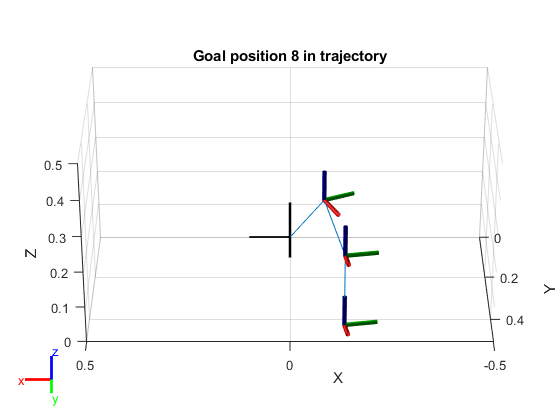

for i = 1:8
    show(densoRobot,goalPos(:,:,i));
    axis([-0.500,0.500,0,0.500,0,0.500]) % Set axes to be like video
    view(180,30) % Adjust camera view
    title(sprintf("Goal position %d in trajectory",i))
    pause(1)
end

### Set Physical Properties

Set masses and moments of inertia.

% Masses for links (in kgs)
linkMass = zeros(4,1);
linkMass(1) = 3.0;
linkMass(2) = 2.75;
linkMass(3) = 2.0;
linkMass(4) = 1;
% Moments of inertia (in kgm^2)
I1 = 0.1;
I2 = 0.1;
I3 = 0; % prismatic
I4 = 0.01;
% Set the masses
body1.Mass = linkMass(1);
body2.Mass = linkMass(2);
body3.Mass = linkMass(3);
body4.Mass = linkMass(4);
% Set the centers of masses
body1.CenterOfMass = [L1/2, 0, 0];
body2.CenterOfMass = [L2/2, 0, 0];
body3.CenterOfMass = [d3/2, 0, 0]; % variable prismatic length
body4.CenterOfMass = [0,0,0];
% Set the inertias
body1.Inertia = [I1,I1,I1,0,0,0];
body2.Inertia = [I2,I2,I2,0,0,0];
body3.Inertia = [0,0,0,0,0,0];
body4.Inertia = [I4,I4,I4,0,0,0];

## Problem 1 (from previous assignment)

The aim of problem 1 is to visualize the joint torques for each joint as the robot moves along the trajectory in the video.

### Force PD Controller

Our approach is to implement a force proportional-derivative controller to start with an arbitrary acceleration and use inverse dynamics to obtain the joint torques.

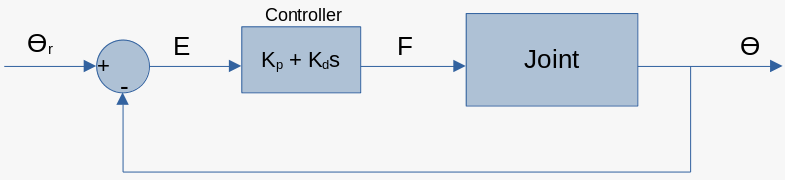

The overall formula for our controller is given as,


$$F=K_p E+K_d \dot{E} =K_p E-K_d v$$


In this formula, the error for our controller, $E$ is calculated as $E=\theta_r -\theta$. This error is then with the proportional multiplier (gain) $K_p$ to obtain the first term of our controller. For the second term, the derivative of the error is calculated as $\dot{E} =\dot{\theta_r } -\dot{\theta} =0-\dot{\theta} =-v$, i.e. the negative of the current velocities of the joints. This derivative of the error is then multiplied with the derivative gain, $K_d$.

For every moment in time, as we move our robot, we can use the controller formula to calculate the new set of forces that we would like to apply to our robot. By dividing the forces by the masses, we obtain the current linear accelerations we would like to apply to the joints. Then, we need to supply these current accelerations, current velocities, and current position to MATLAB's `inverseDynamics` in-built function, in order to output joint torques to apply to our motors.

Now let us set up some variables for our controller.

% Controller proportional gain
Kp = [17;13;100;0];
% Controller derivative gain
Kd = [7;9;11;0];
% Create timing array for controller to run
timeStep = 0.05; % arbitrarily small time step (50 ms)
timeLimit = 50;
timeArr = 0:timeStep:timeLimit;
[~,timeArrLen] = size(timeArr);
% Starting positions, velocities, accelerations
jointPosCurr    = [0;0;0;0];
jointVelsCurr   = [0;0;0;0];
jointAccelsCurr = [0;0;0;0];
% Array for capturing joint torques
jointTorquesArr = zeros(4,1,timeArrLen);

Run our controller, and capture the joint torques.

i = 1;
goalNum = 1;
goalEvent = zeros(1,8);
for t = timeArr
    % Current goal position
    currGoal = goalPos(:,:,goalNum);
    % Calculate error and error-derivative
    error = goalPos(:,:,goalNum) - jointPosCurr;
    error_prime = -1*jointVelsCurr;
    % Form forces via controller equation
    F = Kp.*error + Kd.*error_prime;
    % Form new accelerations
    jointAccelsCurr = F./linkMass;
    % Get joint torques
    jointTorquesArr(:,:,i) = inverseDynamics(densoRobot,jointPosCurr,jointVelsCurr,jointAccelsCurr);
    i = i + 1;
    % Move the robot (update position and velocity)
    jointVelsCurr = jointVelsCurr + jointAccelsCurr*timeStep;
    jointPosCurr  = jointPosCurr + jointVelsCurr*timeStep;
    % Check if we've reached goal within tolerance:
    % 0.05 radian and 0.01 m tolerance
    if (revJntGoalCheck(jointPosCurr(1:2,:),currGoal(1:2,:),0.05) && abs(error(3,1)) <= 0.01)
        fprintf("Reached goal %d\n",goalNum);
        goalEvent(goalNum) = i;
        goalNum = goalNum + 1;
        % Retract prismatic joint
        jointPosCurr(3,1) = 0;
    end
    % Check if we've reached all goals
    if (goalNum > 8)
        fprintf("Reached all goals, stopping.\n");
        break;
    end
end

Reached goal 1
Reached goal 2
Reached goal 3
Reached goal 4
Reached goal 5
Reached goal 6
Reached goal 7
Reached goal 8


Reached all goals, stopping.


### Plot Joint Torques

The objective of this problem is to plot the joint torques that we would apply to the robot joint motors. In order to do this, let us first "flatten" the 3-dimensional list of joint torques.

joint_torque1 = reshape(jointTorquesArr(1,1,:),[1,timeArrLen]);
joint_torque2 = reshape(jointTorquesArr(2,1,:),[1,timeArrLen]);
joint_torque3 = reshape(jointTorquesArr(3,1,:),[1,timeArrLen]);

The following is the plot for the first three joints. We are not concerned with the fourth joint since that is the end-effector joint, which does not affect our robot trajectory.

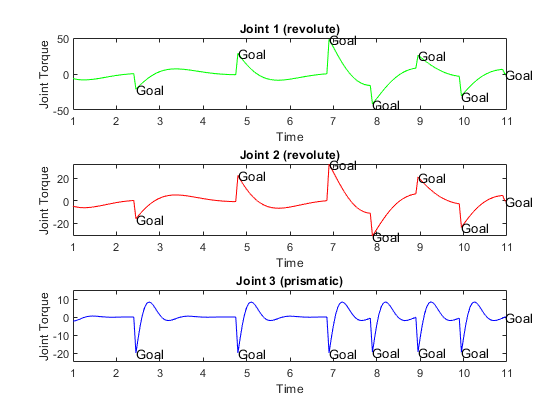

subplot(3,1,1);
plot(timeArr,joint_torque1,'g');
xlabel("Time")
ylabel("Joint Torque")
title("Joint 1 (revolute)")
xlim([1 i*timeStep])
% Label where goals occurred
for marker = 1:i
    if (ismember(marker,goalEvent) && marker ~= min(goalEvent))
        text(timeArr(marker), joint_torque1(marker), "Goal")
    end
end
subplot(3,1,2);
plot(timeArr,joint_torque2,'r');
xlabel("Time")
ylabel("Joint Torque")
title("Joint 2 (revolute)")
xlim([1 i*timeStep])
% Label where goals occurred
for marker = 1:i
    if (ismember(marker,goalEvent) && marker ~= min(goalEvent))
        text(timeArr(marker), joint_torque2(marker), "Goal")
    end
end
subplot(3,1,3);
plot(timeArr,joint_torque3,'b');
xlabel("Time")
ylabel("Joint Torque")
title("Joint 3 (prismatic)")
xlim([1 i*timeStep])
ylim([-25 15])
% Label where goals occurred
for marker = 1:i
    if (ismember(marker,goalEvent) && marker ~= min(goalEvent))
        text(timeArr(marker), joint_torque3(marker), "Goal")
    end
end

## Problem 2 (from previous assignment)

In this problem, our objective is to calculate the joint torques required to balance the static external force that occurs immediately after the robot picks up the set of water bottles. Let us assume that the water bottles weigh 3 kgs. We use the following formula to calculate the joint torques,


$$\tau =J^T \left(q\right)\;\;F$$


Where $\tau$ is the vector of joint torques, $J^T \left(q\right)$ is the transpose of the Jacobian for the manipulator, and $F$is the vector of forces and torques acting at the end effector. First, let us calculate the Jacobian. The textbook form of this Jacobian is a *6 x 4* matrix given as follows,


$$J=\left\lbrack \begin{array}{cccc}
z_0 \times \left(o_4 -o_0 \right) & z_1 \times \left(o_4 -o_1 \right) & z_2  & z_3 \times \left(o_4 -o_3 \right)\\
z_0  & z_1  & 0 & z_3 
\end{array}\right\rbrack$$


Where $z_i$ denotes the *3 x 1* vector for the z-axis of the coordinate frame rigidly assigned to the corresponding link *i*, and $o_i$ denotes the origins for those frames. We find these *z* and *o* vectors as follows. In MATLAB, the geometric Jacobian's angular and linear components in the matrix are swapped, i.e. the angular ones actually appear on top and the linear ones appear at the bottom.

% Choose any goal position where water bottles are picked up
goalExample = goalPos(:,:,3);
% Compute Jacobian
J = geometricJacobian(densoRobot,goalExample,'body4');
% Transpose Jacboain
J_transp = J.';

Now we assume the "wrench" force, i.e. the 3 kg set of water bottles. The wrench vector takes on the form `[Tx; Ty; Tz; Fx; Fy; Fz]`, where the T's are moments, and F's are the forces. Since the prismatic joint moves solely along the z axis, it has no moment, only a force being acted upon it by the water bottles.

wrench = [0; 0; 0; 0; 0; -3*9.8];

Therefore, the joint torques required to balance this weight is given as,

tau = J_transp * wrench

tau =          0
         0
  -29.4000
         0


Which correctly shows that only a balancing torque of -*29.4 Nm* is required by the third joint (prismatic).

## Problem 3

Let us re-set up the controller we built in Problem 1.

% Controller proportional gain
Kp = [17;13;100;0];
% Controller derivative gain
Kd = [7;9;11;0];
% Create timing array for controller to run
timeStep = 0.05; % arbitrarily small time step (50 ms)
timeLimit = 50;
timeArr = 0:timeStep:timeLimit;
[~,timeArrLen] = size(timeArr);
% Starting positions, velocities, accelerations
jointPosCurr    = [0;0;0;0];
jointVelsCurr   = [0;0;0;0];
jointAccelsCurr = [0;0;0;0];
% Array for capturing joint torques
jointTorquesArr = zeros(4,1,timeArrLen);

Set up the wrench forces for picking up the water bottles and dropping off the water bottles.

wrench = [0; 0; 0; 0; 0; -3*9.8];

Set up the goals that are pick up and drop off goals.

% These goals will have no wrench force being applied
pickUpGoals = [1,3,5,7];
% These goals will have wrench force being applied
dropOffGoals = [2,4,6,8];

Run our controller, and capture the joint torques.

i = 1;
goalNum = 1;
goalEvent = zeros(1,8);
for t = timeArr
    % Current goal position
    currGoal = goalPos(:,:,goalNum);
    % Calculate error and error-derivative
    error = goalPos(:,:,goalNum) - jointPosCurr;
    error_prime = -1*jointVelsCurr;
    % Form forces via controller equation
    F = Kp.*error + Kd.*error_prime;
    % Form new accelerations
    jointAccelsCurr = F./linkMass;
    if (ismember(goalNum,dropOffGoals))
        % Calculate external force
        forceExt = externalForce(densoRobot,'body3',wrench,jointPosCurr);
        % Get joint torques
        jointTorquesArr(:,:,i) = inverseDynamics(densoRobot,jointPosCurr,jointVelsCurr,jointAccelsCurr,forceExt);
    else
        % Get joint torques
        jointTorquesArr(:,:,i) = inverseDynamics(densoRobot,jointPosCurr,jointVelsCurr,jointAccelsCurr);
    end
    i = i + 1;
    % Move the robot (update position and velocity)
    jointVelsCurr = jointVelsCurr + jointAccelsCurr*timeStep;
    jointPosCurr  = jointPosCurr + jointVelsCurr*timeStep;
    % Check if we've reached goal within tolerance:
    % 0.05 radian and 0.01 m tolerance
    if (revJntGoalCheck(jointPosCurr(1:2,:),currGoal(1:2,:),0.05) && abs(error(3,1)) <= 0.01)
        fprintf("Reached goal %d\n",goalNum);
        goalEvent(goalNum) = i;
        goalNum = goalNum + 1;
        % Retract prismatic joint
        jointPosCurr(3,1) = 0;
    end
    % Check if we've reached all goals
    if (goalNum > 8)
        fprintf("Reached all goals, stopping.\n");
        break;
    end
end

Reached goal 1
Reached goal 2
Reached goal 3
Reached goal 4
Reached goal 5
Reached goal 6
Reached goal 7
Reached goal 8


Reached all goals, stopping.


### Plot Joint Torques

The objective of this problem is to plot the joint torques that we would apply to the robot joint motors. In order to do this, let us first "flatten" the 3-dimensional list of joint torques.

joint_torque1 = reshape(jointTorquesArr(1,1,:),[1,timeArrLen]);
joint_torque2 = reshape(jointTorquesArr(2,1,:),[1,timeArrLen]);
joint_torque3 = reshape(jointTorquesArr(3,1,:),[1,timeArrLen]);

The following is the plot for the first three joints. We are not concerned with the fourth joint since that is the end-effector joint, which does not affect our robot trajectory.

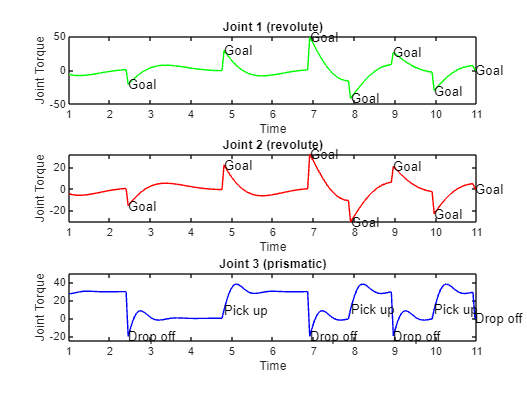

subplot(3,1,1);
plot(timeArr,joint_torque1,'g');
xlabel("Time")
ylabel("Joint Torque")
title("Joint 1 (revolute)")
xlim([1 i*timeStep])
% Label where goals occurred
for marker = 1:i
    if (ismember(marker,goalEvent) && marker ~= min(goalEvent))
        text(timeArr(marker), joint_torque1(marker), "Goal")
    end
end
subplot(3,1,2);
plot(timeArr,joint_torque2,'r');
xlabel("Time")
ylabel("Joint Torque")
title("Joint 2 (revolute)")
xlim([1 i*timeStep])
% Label where goals occurred
for marker = 1:i
    if (ismember(marker,goalEvent) && marker ~= min(goalEvent))
        text(timeArr(marker), joint_torque2(marker), "Goal")
    end
end
subplot(3,1,3);
plot(timeArr,joint_torque3,'b');
xlabel("Time")
ylabel("Joint Torque")
title("Joint 3 (prismatic)")
xlim([1 i*timeStep])
ylim([-25 50])
% Label where goals occurred
goalNum = 2;
for marker = 1:i
    if (ismember(marker,goalEvent) && marker ~= min(goalEvent))
        % Even goals are drop-off and odd goals are pick-up goals
        if (mod(goalNum,2) == 0)
            text(timeArr(marker), joint_torque3(marker), "Drop off")
        else
            text(timeArr(marker), joint_torque3(marker), "Pick up")
        end
        goalNum = goalNum + 1;
    end
end

### Analysis

From the third subplot in the above set of plots, we see where the robot picked up and dropped off the water bottles. We can see that the equilibrium joint torque is much higher for the prismatic joint when it is carrying the water, as compared to when it is not carrying the weight. When we compare this plot to the third subplot from Problem 1, we see that the operating joint force in Problem 1 was always the same for every goal. This makes sense because there was no external force being applied. In this problem (Problem 3), however, there is an external force after picking up the water bottles, which causes the joint torque to shoot up after picking up the water bottles. From the intuition we have developed in this class, this appears to be correct.

## Supporting Functions

The following function checks if a set of revolute joints have achieved their goal by checking if the angles are within the given tolerance zone.

function goalReached = revJntGoalCheck(joints, goals, tolerance)
    truthArr = ismembertol(joints,goals,tolerance);
    goalReached = (sum(truthArr) == size(joints,1));
end